# Simulation von TEMPOL fast motion spectra

TP 4.7.2020

Dieses Program erlaubt die gemessenen fast motion X-band cw-EPR Spektren von TEMPO

zu simulieren und damit die Rotationskorrelationszeit zu bestimmen.

Dazu müssen die einzelnen Spektren eingelesen werden (diese müssen sich im gleichen Ordner befinden oder der Ordner muss in Set Path im Hauptmenü von Matlab gelinkt werden

clear, clf, clc;                     % löscht alle vorherigen Eingaben
Filename='TPOA_EPR_Spektrum';        % Filename des EPR Spektrums 
[B,ExpSpectrum, Param]=eprload('90% 1acc 2mW.DTA');  % lädt den Feldvektor das experimentelle Spektrum und die Parameter

Die Spin-Parameter für TEMPO (g-tensor und hf-tensor) sind gegeben.

Um eine möglichst gute Anpassung der Simulation an das experimentelle Spektrum zu erziehlen können 

gegebenfalls zwei Parameter leicht variiert werden: 

1) gshift (um einen Eichfehler von B zu korrigieren)

2) Sys.lw (die die natürliche Linienbreite und die unaufgelösten weiteren hf Kopplungen beschreibt) Voigt-Linienform ist ein Vektor (konvolution aus Gausslinie + Lorentzlinie)

giso = 2.00577;
gshift=+0.0000;
giso=giso+gshift;
ganiso=[0.0031 0.0004 -0.0035];
Sys.g=giso+ganiso;
Sys.Nucs='14N';
aiso=1.60;     % in mT
aniso=[-1.02 -1.22 2.24];   % in mT
AmT=aiso+aniso;
AMHz=mt2mhz(AmT);
Sys.A=AMHz;
Sys.lw=[0.1 0.052];   % mixture of Lorentzian and Gaussian linewidth in mT

Der entscheidene Parameter der gefunden werden soll ist die Rotationskorrelationszeit tcorr

Sys.tcorr=1.13*1e-9;              % rotational correlation time in s

 Die Experimentellen Parameter werden für die Simulation verwendet:

Exp.mwFreq = Param.MWFQ / 1e9; % MW-Frequenz aus Experiment Parametern
Exp.Range = [Param.XMIN Param.XMIN+Param.XWID] / 10; %Param Field in Units of Gauss, easyspin expectes mT
Exp.nPoints = Param.XPTS; % die Anzahl der Punkte im Spektrum

Das Experimentelle Spektrum wird Baseline-Korrigert und auf +/-1 Normiert

% Spektrum maximum und minimum finden
imax = max(ExpSpectrum); imin = min(ExpSpectrum); 
% Baseline aus ersten 100 Punkten
imean = mean(ExpSpectrum(1:100));
% Spektrum auf -1 bis +1 'normieren'
ExpSpectrum = (ExpSpectrum-imean) / (imax-imin) * 2 ;

Jetzt wird das cw-EPR Spektrum mit den gegebenen Spin-Hamilton-Parametern simuliert und mit dem experimentellen Spektrum verglichen:

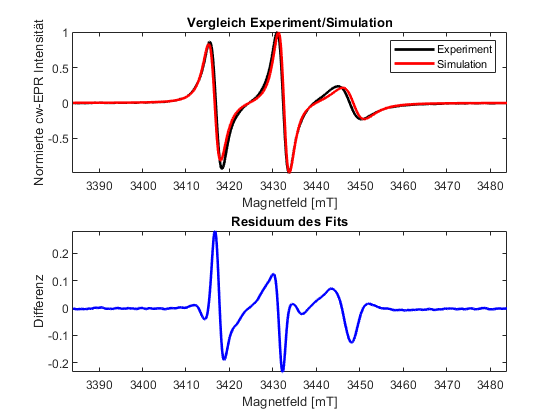

SimSpectrum = garlic(Sys,Exp);     % für fast motion cw-EPR Spektren
SimSpectrum=SimSpectrum/max(SimSpectrum); % Normierung auf +/- 1
SimSpectrum=SimSpectrum';   % Von Zeilen zu Spaltenvektor
subplot(211)
plot(B,ExpSpectrum,'k',B,SimSpectrum,'r','LineWidth',2);
axis tight
legend('Experiment', 'Simulation');  % Beschriftung
xlabel('Magnetfeld [mT]','FontSize',15);
ylabel('Normierte cw-EPR Intensität','FontSize',15);
title('Vergleich Experiment/Simulation')
subplot(212)
plot(B,ExpSpectrum-SimSpectrum,'b','LineWidth',2);
axis tight
xlabel('Magnetfeld [mT]','FontSize',15);
ylabel('Differenz','FontSize',15);
title('Residuum des Fits')